# Differential Kinematics

## Modeling and Control of Robotic Manipulators

## Jacobian Calculation with Symbolic Toolbox

#### 1. Compute geometric Jacobian

Compute the $$6 \times 2$$ **geometric** Jacobian $$\mathbf{J}(\mathbf{q})$$ as a function of $$\mathbf{q}=[\theta_1, \theta_2]^T$$ for the planar two link arm. Set parameters $$a_1=a_2=1$$. The symbolic toolbox can be utilized to perform linear algebra including symbolic variables $$\theta_1$$, $$\theta_2$$. Declare the symbolic variables with `syms theta1 theta2`. The resulting expression might be simplified using '`simplify`'.

syms theta1 theta2;
 
A1 = [cos(theta1) -sin(theta1) 0 cos(theta1);
      sin(theta1) cos(theta1) 0 sin(theta1);
      0 0 1 0;
      0 0 0 1];
A2 = [cos(theta2) -sin(theta2) 0 cos(theta2);
      sin(theta2) cos(theta2) 0 sin(theta2);
      0 0 1 0;
      0 0 0 1];
T = simplify(A1*A2);

p0 = [0 0 0]';
p1 = A1(1:3,4);
p2 = T(1:3,4);
% Geometric Jacobian
zi = [0 0 1]'; 
Jp = [cross(zi, p2-p0), cross(zi, p2-p1)];
J = simplify([ Jp; [zi zi]]) % rotational part: revolute joints only

$$J = \left(\begin{array}{cc} -\sin\left(\theta_{1}+\theta_{2}\right)-\sin\left(\theta_{1}\right) & -\sin\left(\theta_{1}+\theta_{2}\right)\\ \cos\left(\theta_{1}+\theta_{2}\right)+\cos\left(\theta_{1}\right) & \cos\left(\theta_{1}+\theta_{2}\right)\\ 0 & 0\\ 0 & 0\\ 0 & 0\\ 1 & 1 \end{array}\right)$$

#### 2. Substitute symbolic variables

Calculate the geometric Jacobian in numerical form for a joint configuration $$\mathbf{q} = [\frac{\pi}{2},-\frac{\pi}{2}]$$. In order to evaluate the symbolic Jacobian expression for a specific joint configuration employ `subs` to substitute symbolic variables by numerical variables in a symbolic expression.

J2 = double(subs(J, [theta1, theta2], [pi/2, -pi/2])) 

J2 =     -1     0
     1     1
     0     0
     0     0
     0     0
     1     1


#### 3. Compute analytic Jacobian

Compute the $$6 \times 2$$ **analytic** Jacobian $$\mathbf{J}_A$$ of the end effector pose $$[x,y,z,\phi,\theta,\psi]^T$$. Since the arm operates in the x-y plane, the z-component is always $$z=0$$. The roll-pitch-yaw angles are defined by $$\phi=0, \theta=0, \psi=\theta_1+\theta_2$$. $$x$$ and $$y$$ are part of the forward kinematics $$\mathbf{T}_2^0(\mathbf{q})$$. Calculate the derivatives with the '`jacobian`' function of the symbolic toolbox w.r.t. to $$\theta_1$$ and $$\theta_2$$. Evaluate the analytic Jacobian in numerical form for the joint configuration $$\mathbf{q} = [\frac{\pi}{2},-\frac{\pi}{2}]$$.

% analytic jacobian (translation only)
JAp = J(1:3,:);
phi = 0;
theta = 0;
psi = theta1 + theta2;
JAo = jacobian([phi; theta; psi], [theta1, theta2]);
JA = [JAp; JAo];
JA2 = double (subs(JA, [theta1, theta2], [pi/2, -pi/2]))

JA2 =     -1     0
     1     1
     0     0
     0     0
     0     0
     1     1


## Geometric Jacobian Robotics System Toolbox

#### 4. Build Rigid Body Tree Model of two link planar arm

Define the rigid body tree model for the two link planar arm and examine its structure.

a1=1.0; % link length first link
a2=1.0; % link length second link

robot = robotics.RigidBodyTree;
robot.BaseName='base';

link1 = robotics.RigidBody('link1');
jnt1 = robotics.Joint('joint1','revolute');
jnt1.setFixedTransform([a1 0 0 0],'dh');
link1.Joint = jnt1;
robot.addBody(link1,'base');

link2 = robotics.RigidBody('link2');
jnt2 = robotics.Joint('joint2','revolute');
jnt2.setFixedTransform([a2 0 0 0],'dh');
link2.Joint = jnt2;
robot.addBody(link2,'link1');

robot.showdetails();

--------------------
Robot: (2 bodies)

 Idx    Body Name    Joint Name    Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------    ----------    ----------    ----------------   ----------------
   1        link1        joint1      revolute             base(0)   link2(2)  
   2        link2        joint2      revolute            link1(1)   
--------------------


#### 5.  Determine the geometric Jacobian

Determine the geometric Jacobian for the joint configuration $$[\theta_1 \ \theta_2]=[\pi/2 \ -\pi/2]$$ of the two link arm with `geometricJacobian`.

q1 = pi/2;
q2 = -pi/2;
conf = JointVec2JointConf(robot,[q1; q2]);
Jgr = geometricJacobian(robot,conf,'link2')

Jgr =      0     0
     0     0
     1     1
    -1     0
     1     1
     0     0


#### 6. Verify the Jacobian

Verify that the Jacobian is equal to the numerical solution obtained from the symbolic expression of the Jacobian in 2.

temp = [JA2(4:6,:); JA2(1:3,:)];
if temp == Jgr
    display('symbolic Jacobian and Robotics Toolbox Jacobian are equal');
else
    display('mismatch symbolic Jacobian and Robotics Toolbox Jacobian');
end

symbolic Jacobian and Robotics Toolbox Jacobian are equal


#### 7. Determine the `rank` of the translational velocity part of the geometric Jacobian 

Determine the `rank` of the translational velocity part of the geometric Jacobian $$\mathbf{J}_p$$ for the joint configuration $$[\theta_1 \ \theta_2]=[\pi/2 \ -\pi/2]$$ and the joint configuration $$[\theta_1 \ \theta_2]=[0 \ 0]$$ of the two link arm with `geometricJacobian`. What happens in the outstretched arm configuration?

Check for rank of position part of Jacobian kinematic singularity for the joint configuration $$[\theta_1 \ \theta_2]=[\pi/2 \ -\pi/2]$$ 

display(['rank of J for theta1=' num2str(q1) ' theta2=' num2str(q2) ' : ' num2str(rank(Jgr(4:6,:)))]);

rank of J for theta1=1.5708 theta2=-1.5708 : 2


Check for rank of position part of Jacobian kinematic singularity for the joint configuration $$[\theta_1 \ \theta_2]=[0 \ 0]$$

q1 = 0;
q2 = 0;
conf2 = JointVec2JointConf(robot,[q1; q2]);
Jgr2 = geometricJacobian(robot,conf2,'link2'); 
display(['rank of J for theta1=' num2str(q1) ' theta2=' num2str(q2) ' : ' num2str(rank(Jgr2(4:6,:)))]);

rank of J for theta1=0 theta2=0 : 1


#### 8. Import UR10

Import the UR10 rigid body object *ur10* from the file *'ur10.urdf'*.

ur10 = importrobot('ur10.urdf');
ur10.showdetails();

--------------------
Robot: (8 bodies)

 Idx             Body Name                 Joint Name                 Joint Type             Parent Name(Idx)   Children Name(s)
 ---             ---------                 ----------                 ----------             ----------------   ----------------
   1             base_link                world_joint                      fixed                     world(0)   shoulder_link(2)  
   2         shoulder_link         shoulder_pan_joint                   revolute                 base_link(1)   upper_arm_link(3)  
   3        upper_arm_link        shoulder_lift_joint                   revolute             shoulder_link(2)   forearm_link(4)  
   4          forearm_link                elbow_joint                   revolute            upper_arm_link(3)   wrist_1_link(5)  
   5          wrist_1_link              wrist_1_joint                   revolute              forearm_link(4)   wrist_2_link(6)  
   6          wrist_2_link              wrist_2_j

#### 9. Compute Jacobian for the UR10 arm w.r.t. to the base

Compute the Jacobian for the *ur10* arm for a joint configuration $$\mathbf{q}_0=[-3/4 \pi \ 0.3 \ 0.3 \  0  \ \pi/8 \ 0]$$ w.r.t. to the base $$\mathbf{J}_w$$.

% % joint configuration
q0 = [-3*pi/4 0.3 0.3 0 pi/8 0]';
confq0 = JointVec2JointConf(ur10, q0);
% Jacobian in world frame
Jw = geometricJacobian(ur10, confq0, 'ee_link')

Jw =    -0.0000    0.7071    0.7071    0.7071    0.3993    0.4299
   -0.0000   -0.7071   -0.7071   -0.7071    0.3993   -0.8766
    1.0000   -0.0000   -0.0000   -0.0000   -0.8253   -0.2161
    0.8980    0.4380    0.3101    0.0816   -0.0747   -0.0000
   -0.5457    0.4380    0.3101    0.0816   -0.0248   -0.0000
         0   -1.0208   -0.4361    0.0362   -0.0481   -0.0000


#### 10. Compute the Jacobian for the same configuration w.r.t. end effector frame.

Compute the Jacobian for the same configuration w.r.t. end effector frame $$\mathbf{J}_e$$ according to equation 11. You obtain $$\mathbf{R}^u$$ from rotation matrix (`tform2rotm`) of the end effector transform `getTransform`.

Re = [tform2rotm(ur10.getTransform(confq0, 'ee_link')) zeros(3,3); zeros(3,3) tform2rotm(ur10.getTransform(confq0, 'ee_link'))];
% Jacobian in end effector frame
Je = Re*Jw

Je =     0.3993    0.8766    0.8766    0.8766   -0.4812    0.8084
    0.3993   -0.4299   -0.4299   -0.4299   -0.7868   -0.2277
   -0.8253    0.2161    0.2161    0.2161    0.3866    0.5427
    0.8279   -0.5739   -0.2919   -0.0165   -0.0313   -0.0000
   -0.6406   -0.9092   -0.5293   -0.0790    0.0529    0.0000
    0.0906    0.5194    0.1312   -0.0901    0.0687    0.0000


## Resolved Rate Motion Control

#### 11. Compute velocity vector that corresponds to a translational motion

Compute the joint velocity vector *qdot* ($$\dot{\mathbf{q}}$$) according to (12) that corresponds to a translational motion in the x-y plane in conjunction with a rotation of the end effector frame around  y- and z-axis in task space 

$$\dot{\mathbf{x}}_d= [  \omega_x\;   \omega_y\;   \omega_z\;  \dot p_x\;    \dot p_y\;  \dot p_z ]^T=[0\; \pi/30 \; \pi/15 \; 0.4\; 0.2\; 0.2]^T$$.

% x_dot = J(q)*q_dot

% desired task space velocity xdotx=[wx wy wz vx vy vz]
xdotd = [0 pi/30 pi/15 0.4 0.2 0.2]';

% determine joint velocities using the inverse of the jacobian Jw:
qdot = inv(Jw)*xdotd

qdot =     0.1379
   -2.2862
    4.7076
   -2.2504
   -0.0172
   -0.2652


#### 12-13. Assume a  task space reference trajectory; Calculate the array of corresponding transforms

Assume a  task space reference trajectory generated according to $\mathbf{x}_d(t)=\mathbf{x}_0 + \dot{\mathbf{x}}_d t ,$ in which $$\mathbf{x}_0$$ denotes the initial pose given by the forward kinematics $$\mathbf{k}(\mathbf{q}_0)$$ ($$\mathbf{q}_0=[-3/4 \pi \ 0.3 \ 0.3 \  0  \ \pi/8 \ 0]$$) and $$t \in [0\; 4.0]$ with $\Delta t=0.2$$. The generalized velocity vector $$\dot{\mathbf{x}}_d =[\mathbf{\omega} \; \mathbf{v}]^T$$ is a constant task space velocity. 

Calculate the array of corresponding transforms *tformxd* from *xdotd *by concatenation of the initial rotation $$\mathbf{H}_{rot_0}$$ and the incremental rotation $$H(\mathbf{\omega}\cdot t)$$, followed by the initial translation $$\mathbf{H}_{trans_0}$$ and the incremental translation transform $$\mathbf{H}(\mathbf{v}\cdot t)$$.

% Open-loop control / numerical integration

% desired task space velocity xdotx=[wx wy wz vx vy vz]
xdotd = [0 pi/30 pi/15 0.4 0.2 0.2];
% initial joint configuration
q0 = [-3*pi/4 0.3 0.3 0 pi/8 0];
confq0 = JointVec2JointConf(ur10, q0);

% Take the transformation matrix in between the end effector and base frame and
% split them into 2 transformation matrices since the rotational part is
% the final transformation for orientation and the translation part is the final
% transformation for position. To obtain intermediate transformations that
% give the intermediate poses, do the following:
%
% The desired euler angles multiplied with time instants
% then multiplied with initial rotation matrix is multiplied by the 
% desired linear velocity multiplied with time instants
% then multiplied with initial translation matrix.
%
% These transformation matrices will be put in a 3 dimensional matrix where
% 2 dimensions hold the homogeneous transformations and the third dimension
% is for the time.

% initial pose as homogeneous transformation
tformx0 = ur10.getTransform(confq0,'ee_link');
% translation part only
tformtvecx0 = trvec2tform(tform2trvec(tformx0));
% rotation part only
tformrotmx0 = rotm2tform(tform2rotm(tformx0));

% time delay deltat=0.2 for 12-21; delta=0.05 for 22
deltat = 0.2;
% time vector
t = 0:deltat:4.0;
% array of empty transforms
tformxd = zeros(4,4,length(t));

% homogeneous transforms reference trajectory
% composed of initial rotation, rotation part, initial translation, translation part 
% notice the default Euler convention is ZYX, therefore xdotx[3 2 1]
for k= 1:length(t)
    tformxd(:,:,k) = trvec2tform(xdotd(4:6)*t(k))*tformtvecx0*eul2tform(xdotd([3 2 1])*t(k))*tformrotmx0;
end

#### 14. Plot the translation and orientations

Plot the translation (*tform2trvec*) and orientation in axis-angles (*tform2axang*) of the reference transforms *tformxd* over time as shown in the top row in Figure 2.

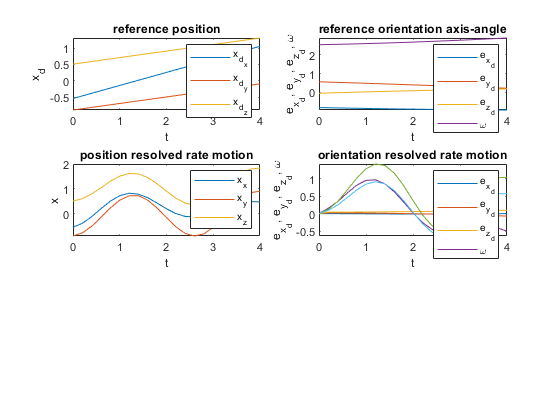

figure(1);
subplot(321);
evo_translation = tform2trvec(tformxd);
evo_rotation = tform2axang(tformxd);

plot(t, evo_translation)
xlabel('t');
ylabel('x_d');
legend('x_{d_x}','x_{d_y}','x_{d_z}','Location','northeast');
title('reference position');

subplot(322);
plot(t, evo_rotation);
xlabel('t')
ylabel('e_{x_d}, e_{y_d}, e_{z_d}, \omega')
legend('e_{x_d}', 'e_{y_d}', 'e_{z_d}', '\omega','Location','southeast');
title('reference orientation axis-angle');

#### 15. Integrate the joint configuration at fixed time intervals

Integrate the joint configurations at fixed time intervals $$t_k = k \Delta t$$ with $$\Delta t =0.2$$.


$$\mathbf{q}_{k+1} = \mathbf{q}_k + \mathbf{J}_w(\mathbf{q}_0)^{-1} \dot{\mathbf{x}}_d \Delta t$$


This integration ignores the fact that $$\mathbf{J}_w(\mathbf{q})$$ varies along the trajectory but only considers the static Jacobian $$\mathbf{J}_w(\mathbf{q}_0)$$ . Compute the joint space trajectory $$\mathbf{q}_k$$ by iterating equation (18) and determine the actual trajectory *tformx* in the workspace $$\mathbf{x}_k=\mathbf{k}(\mathbf{q}(t_k))$$ from forward kinematics (`getTransform()`). 

tformx = zeros(4,4,length(t));
poseerror = zeros(6,length(t));
q = zeros(6,length(t));
q(:,1) = q0;
tformx(:,:,1) = ur10.getTransform(confq0, 'ee_link');

% mode for constant Jacobian, or varying Jacobian

switch between task 15 and 20:

mode='constJ'; % task 15-19) 
% mode='varJ';  % task 20-22)

for k=1:length(t)-1
    switch mode
        case 'constJ'   % 15)
            % Open-loop control with const jacobian (w.r.t. reference configuration q0)
            % resolved rate motion control with constant Jacobian J(q0)
            q(:,k+1) = q(:,k) + ur10.geometricJacobian(confq0,'ee_link')\xdotd'*deltat; 
        case 'varJ' % 20
            % Open-loop control with varying jacobian (w.r.t. current configuration q)
            % Advanced resolved rate motion control with J(q_k)
             q(:,k+1)=q(:,k) + ur10.geometricJacobian(JointVec2JointConf(ur10,q(:,k)),'ee_link')\xdotd' * deltat;
    end
    tformx(:,:,k+1) = ur10.getTransform(JointVec2JointConf(ur10, q(:,k+1)),'ee_link');
    poseerror(:,k+1) = robotics.manip.internal.IKHelpers.poseError(tformx(:,:,k+1),tformxd(:,:,k));
end


#### 16. Plot the trajectory

Plot the actual trajectory in terms of translational and orientation part similar to assignment 14 as shown in the middle row of Figure 2.

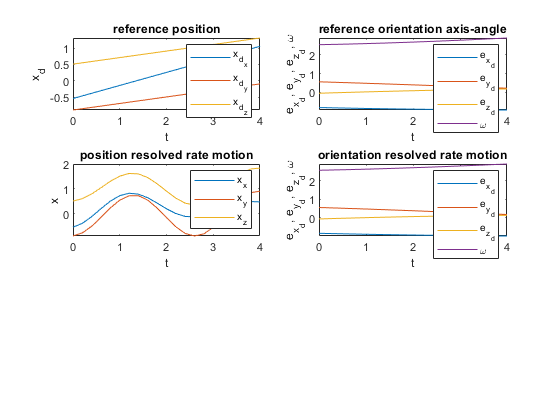

figure(1);
subplot(323);
plot(t, tform2trvec(tformx));
xlabel('t')
ylabel('x');
legend('x_x','x_y','x_z','Location','northeast');
title('position resolved rate motion');

subplot(324);
plot(t, tform2axang(tformx));
xlabel('t');
ylabel('e_{x_d}, e_{y_d}, e_{z_d}, \omega')
legend('e_{x_d}', 'e_{y_d}', 'e_{z_d}', '\omega','Location','southeast');
title('orientation resolved rate motion');

#### 17. Plot the position and orientation errors between actual and nominal trajectories

Plot the position and orientation errors between actual and nominal trajectories as shown in the bottom row of Figure 2.

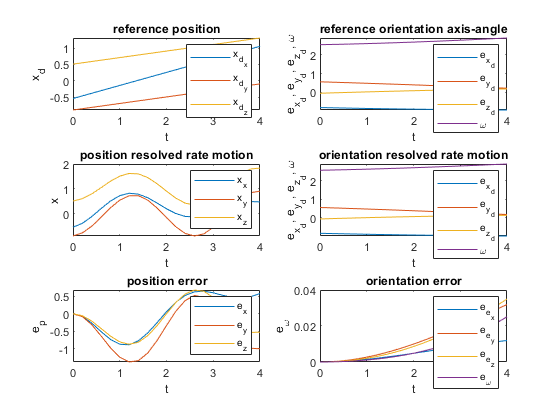

subplot(325);
plot(t,tform2trvec(tformxd)-tform2trvec(tformx));
xlabel('t');
ylabel('e_p');
legend('e_x','e_y','e_z','Location','northeast');
title('position error');

subplot(326);
plot(t,tform2axang(tformxd)-tform2axang(tformx));
xlabel('t');
ylabel('e_\omega')
legend('e_{e_x}', 'e_{e_y}', 'e_{e_z}', 'e_\omega','Location','southeast');
title('orientation error')

#### 18. Calculate and report the norm of the final position error

Calculate and report the norm of the final position error between reference and actual trajectory.

display(['final position error=' num2str(norm(tform2trvec(tformxd(:,:,end))-tform2trvec(tformx(:,:,end))))]);

final position error=1.2719


#### 19. Plot the 3D-position of the end effector frame

Plot the 3D-position of the end effector frame  $$x(t),y(t),z(t)$$ for the reference and actual trajectory. 

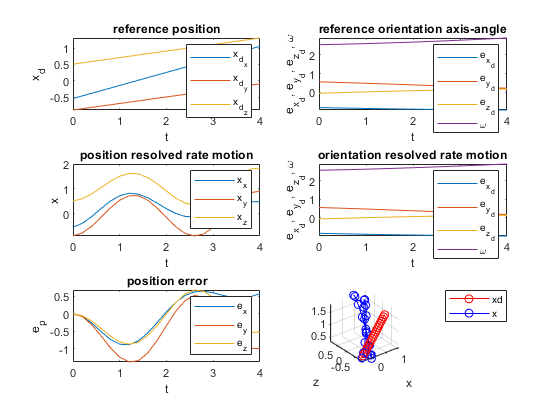

figure(2);
% plot path in x-y plane
pd=tform2trvec(tformxd);
p=tform2trvec(tformx);
plot3(pd(:,1),pd(:,2),pd(:,3),'r-o',p(:,1),p(:,2),p(:,3),'b-o');
grid on;

xlabel('x');
ylabel('y');
ylabel('z');
legend('xd','x');
axis equal;

#### 20. Modify your integration scheme in Section 15

Modify your integration scheme such that it computes the joint space trajectory  by iterating equation (17).

#### 21. Repeat steps

Repeat the steps 16-19 with the modified integration scheme.

#### 22. Reduce integration timt in Section 12-13

 Reduce the integration time to $$\Delta =0.05$$. Compare the final position errors for $$\Delta =0.2$$ and $$\Delta =0.05$$.

#### 23. Visualize the arm motion either in Matlab with `show` or in ROS with RVIZ

Visualize the arm motion either in Matlab with `show` or in ROS with RVIZ. Reutilize the code for visualization in real time from the assignment on Forward Kinematics.

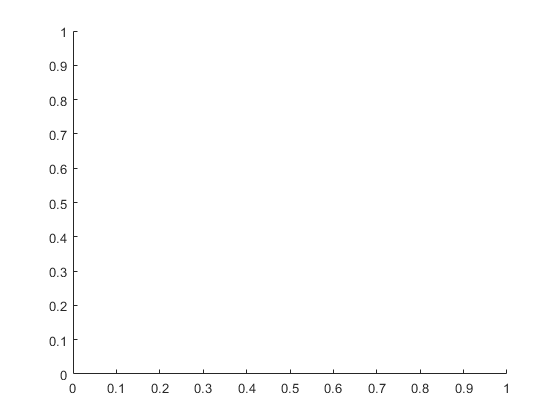

% visualize arm motion
displayMatlab = true;
displayRVIZ = false;

if (displayRVIZ)
    % rosinit('...')
    % jointstatepublisher = rospublisher('/ur10/joint_states','sensor_msgs/JointState');
    % jointstatemsg=rosmessage('sensor_msgs/JointState');
    % jointstatemsg.Header.Stamp=rostime('now');
end    

rate = 20; % Rate of 20 Hz
rateObj=robotics.Rate(rate);
maxTime = 4;

figure(3);
hold off;
pause(1);
rateObj.reset;  % reset time at the beginning of the loop
while rateObj.TotalElapsedTime < maxTime
    
    % get the index for our configuration dependening on time
    k=max(1,min(ceil(rateObj.TotalElapsedTime/deltat),length(t)));
    
    % conf=JointVec2JointConf(ur10,q(:,k));
    
    if (displayMatlab)
        ur10.show(conf);
    end
    
    if (displayRVIZ)
        for i=1:6
            jointstatemsg.Name(i)=cellstr(conf(i).JointName);
            jointstatemsg.Position(i)=conf(i).JointPosition;
        end
        jointstatemsg.Header.Stamp=rostime('now');
        jointstatepublisher.send(jointstatemsg);
    end
    
    waitfor(rateObj);
end

disp('Loop ended');

Loop ended
